# Simular trayectorias en el espacio articular (Joint-Space Motion Model)

El modelo de movimiento del espacio articular (Joint-Space Motion Model) caracteriza el movimiento en lazo cerrado de un robot dentro del espacio articular. La acción del control se define en el espacio articular en función de la configuración articulación deseada. 

Hay tres tipos de control en el espacio articular:

- **Independent Joint Motion**: Cada articulación se modela de manera independiente como un sistema de segund orden. Este modelo puede considerarse el mejor escenario de cómo puede comportarse el movimiento en bucle cerrado, ya que la dinámica está simplificada y prescrita directamente.

- **Computed Torque Control: **La dinámica del cuerpo rígido se modela utilizando las ecuaciones de movimiento estándar, pero compensando la dinámica del cuerpo completo y asignando una dinámica de error. Se trata de una versión de mayor fidelidad del control de movimiento de las articulaciones independientes.

- **Proportional-Derivative (PD) contro**l. La dinámica del cuerpo rígido se modela utilizando las ecuaciones de movimiento estándar con una entrada de par conjunta dada por el control proporcional-derivativo (PD). Este modelo representa un controlador que no compensa de forma estricta los efectos globales del movimiento del cuerpo rígido.

Para más información: [https://es.mathworks.com/help/robotics/ug/joint-space-motion-model.html](https://es.mathworks.com/help/robotics/ug/joint-space-motion-model.html)

Vamos a simular trayectorias punto a punto desde las mismas condiciones iniciales y finales utilizando estos tres tipos de control.

## Definimos parámetros iniciales

Cargamos el robot IABB IRB 120T y definimos los parámetros de la simulación. El estado inicial se define como `[joint configuration; jointVelocity]`

%Load robot
robot = loadrobot("abbIrb120T","DataFormat","column","Gravity",[0 0 -9.81]);
numJoints = numel(homeConfiguration(robot));

% Set up simulation parameters
tSpan = 0:0.01:0.5;
q0 = zeros(numJoints,1);
q0(2) = pi/4; % Something off center
qd0 = zeros(numJoints,1);
initialState = [q0; qd0];

% Set up joint control targets
targetJointPosition = [pi/2 pi/3 pi/6 2*pi/3 -pi/2 -pi/3]';
targetJointVelocity = zeros(numJoints,1);
targetJointAcceleration = zeros(numJoints,1);

## Comportamiento con diferentes modos de control en el espacio articular

Con el objeto [`jointSpaceMotionModel`](docid:robotics_ref.mw_d82cc727-9467-4934-870a-2b0ca4917f2b) se puede simular un modelo de posición en lazo cerrado con diferentes tipos de controladores (control de par, control independiente y control PD). Veamos diferentes ejemplos

### Computed-Torque Control

El control de par utiliza la dinámica inversa para compensar la dinámica del robot. El controlador maneja la dinámica de error en lazo cerrado de cada articulación basándose en una respuesta de segundo orden. Se puede actualizar la señal de error utilizando [`updateErrorDynamicsFromStep`](docid:robotics_ref.mw_500e3b60-13f0-49d5-a642-2636a0fd346b)`, e`specificando el tiempo de estabilicación `(`settling time y sobrepico). Alternativamente, se puede establecer la relación de amortiguamiento (damping ratio) y frecuencia natural.

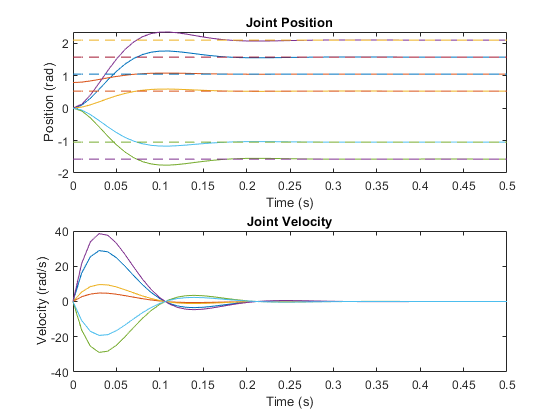

%Create jointSpaceMotionModel 
computedTorqueMotion = jointSpaceMotionModel("RigidBodyTree",robot,"MotionType","ComputedTorqueControl");
%Update values of NaturalFrequency and DampingRatio properties given desired step response
settlingTime =0.2;      %0.2
overshoot = 0.12;       %0.1
updateErrorDynamicsFromStep(computedTorqueMotion,settlingTime,overshoot);
qDesComputedTorque = [targetJointPosition; targetJointVelocity; targetJointAcceleration];
%Simulate using ODE solve
[tComputedTorque,yComputedTorque] = ode45(@(t,y)derivative(computedTorqueMotion,y,qDesComputedTorque),tSpan,initialState);
%Plot results
plotJointPositionSpeed (tComputedTorque, yComputedTorque, targetJointPosition, numJoints);

### Independent Joint Control

Con el control independiente de articulaciones, cada articulación se modela como un sistema de segundo orden independiente. Este tipo modelo modela un comportamiento idealizado, y se utiliza mejor cuando la respuesta es lenta o la dinámica del robot no tendrá un impacto significativo en la trayectoria resultante. En estos casos, se comportará igual que al control por par, pero con menos sobrecarga computacional. 

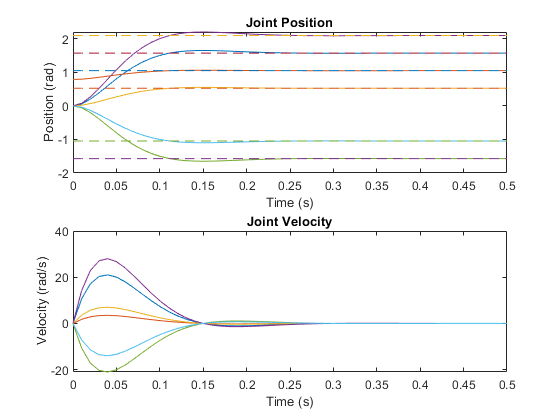

%Create jointSpaceMotionModel 
IndepJointMotion = jointSpaceMotionModel("RigidBodyTree",robot,"MotionType","IndependentJointMotion");
%Update values of NaturalFrequency and DampingRatio properties given desired step response
settlingTime =0.2;      %0.2
overshoot = 0.05;       %0.1
updateErrorDynamicsFromStep(IndepJointMotion,settlingTime,overshoot);
qDesIndepJoint = [targetJointPosition; targetJointVelocity; targetJointAcceleration];
%Simulate using ODE solve
[tIndepJoint,yIndepJoint] = ode45(@(t,y)derivative(IndepJointMotion,y,qDesIndepJoint),tSpan,initialState);
%Plot results
plotJointPositionSpeed (tIndepJoint, yIndepJoint, targetJointPosition, numJoints);

### Proportional-Derivative Control

El control proporcional-derivativo o control PD, combina la compensación de la gravedad y las ganancias proporcionales y derivativas. Las ganancias del controlador PD se establecen como matrices nxn, donde n es el número de articulaciones del robot. Este control no necesita establcer un perfil de aceleración, a diferencia de los anteriores.

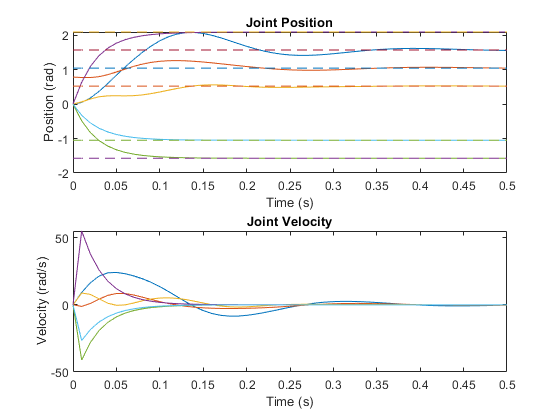

%Create jointSpaceMotionModel 
pdMotion = jointSpaceMotionModel("RigidBodyTree",robot,"MotionType","PDControl");
Kp = 370;   %kp=300
Kd = 10;    %kd= 10
pdMotion.Kp = diag(Kp*ones(1,6));
pdMotion.Kd = diag(Kd*ones(1,6));
qDesPD = [targetJointPosition; targetJointVelocity];
%Simulate using ODE solver
[tPD,yPD] = ode15s(@(t,y)derivative(pdMotion,y,qDesPD),tSpan,initialState);
%Plot results
plotJointPositionSpeed (tPD, yPD, targetJointPosition, numJoints);

## Visualize the Trajectories as an Animation

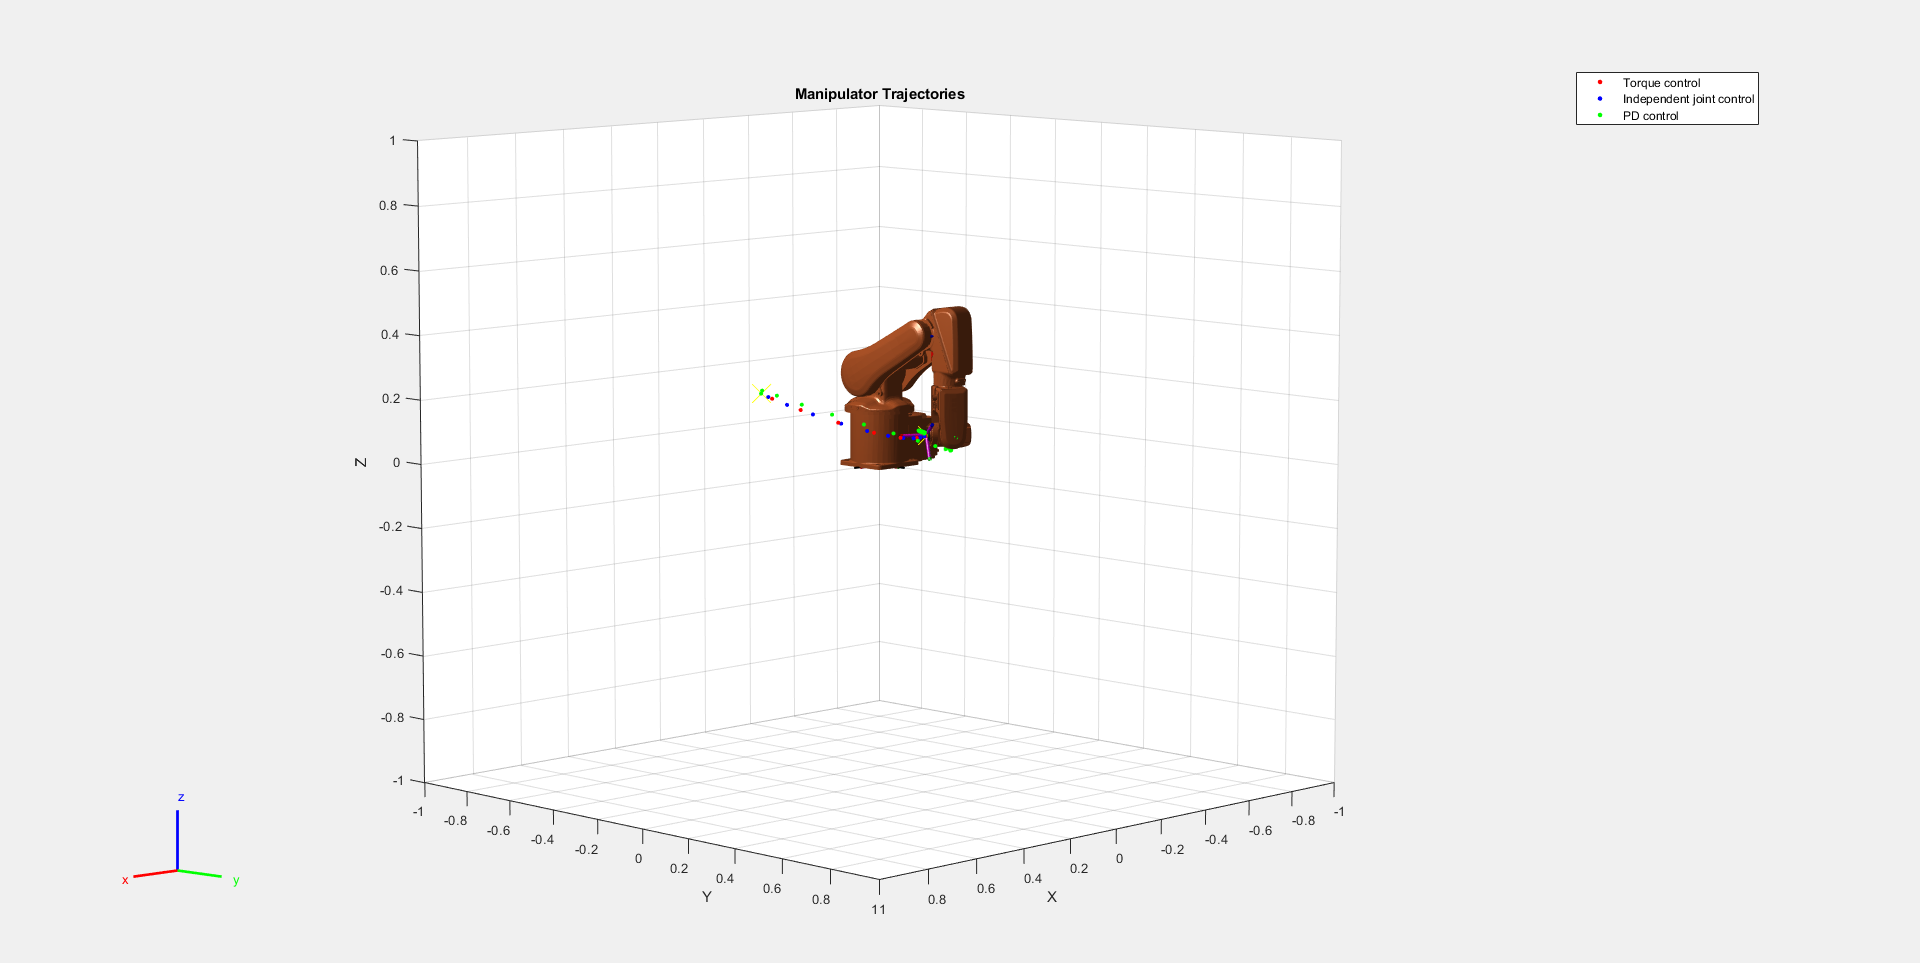

endEffector = "tool0";
numInputs = numel(homeConfiguration(robot));
initPose = getTransform (robot, q0, endEffector);
targetPose = getTransform (robot, targetJointPosition, endEffector);
r = rateControl(5);

figure
set(gcf,'Visible','on')
show(robot,q0,'PreservePlot',false,'Frames','off');
hold on
plot3(initPose(1,4),initPose(2,4),initPose(3,4),'x','Color','k',"MarkerSize",20)
plot3(targetPose(1,4),targetPose(2,4),targetPose(3,4),"x",'Color','k',"MarkerSize",20)


%COMPUTED TORQUE MOTION
for i = 1:size(yComputedTorque,1)
    poseNow = getTransform(robot,yComputedTorque(i,1:numInputs)',endEffector);
    show(robot,yComputedTorque(i,1:numInputs)',"PreservePlot",false);
    torqueControlpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',10);
    title(sprintf('COMPUTED TORQUE MOTION - Frame = %d of %d', i, length(yComputedTorque)));
    waitfor (r);
end

%INDEPENDENT JOINT MOTION
for i = 1:size(yIndepJoint,1)
    poseNow = getTransform(robot,yIndepJoint(i,1:numInputs)',endEffector);
    show(robot,yIndepJoint(i,1:numInputs)',"PreservePlot",false);
    iControlJointSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',10);
    title(sprintf('INDEPENDENT JOINT MOTION - Frame = %d of %d', i, length(yIndepJoint)));
    waitfor (r);
end

%PD CONTROL
for i = 1:size(yPD,1)
    poseNow = getTransform(robot,yPD(i,1:numInputs)',endEffector);
    show(robot,yPD(i,1:numInputs)',"PreservePlot",false);
    pdControlSpaceMarker = plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'g.','MarkerSize',10);
    title(sprintf('PD CONTROL - Frame = %d of %d', i, length(yPD)));
    drawnow;
end
% Add a legend and title
legend([torqueControlpaceMarker iControlJointSpaceMarker pdControlSpaceMarker], {'Torque control', 'Independent joint control', 'PD control'});
title('Manipulator Trajectories')